# **问题5：阶梯有多少年历史了？这个估计的可靠性如何？**

沿着第四问的思路，已知条件和模拟条件不变，阶梯的实际使用时间为T，我们仍然依靠它来”模拟“真实数据。

但是当我们进行预测和分析时，我们不知道T，故而只能给出一个预测的阶梯的使用时间随机变量t。建立优化模型具体如下：

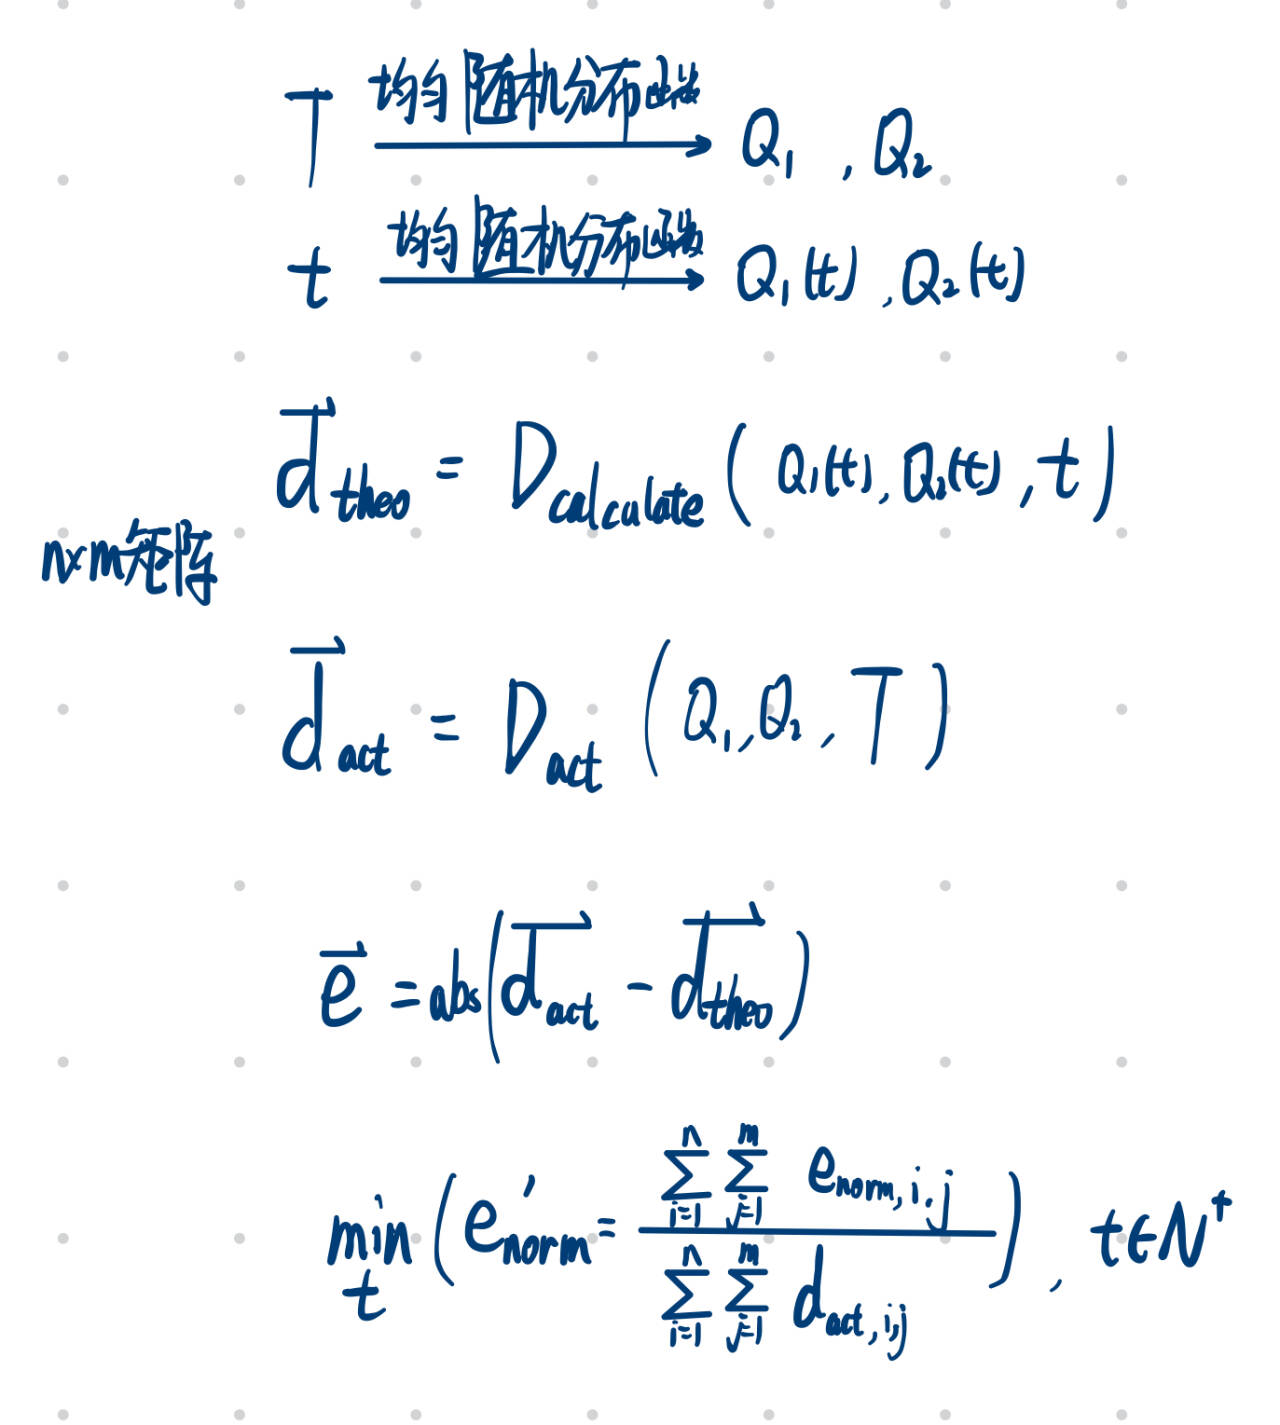  

 ***to ljy:***

clear;clc;
% 设置随机种子
rng(42);
load F.mat;
load P.mat;
% 参数设置
L1 = 1.5; % 单位：m
L2 = 0.40; % 单位：m
m = 120; % 网格大小
n = 32; % 网格大小
T = 120;% 120月
t_max = 144;
t_min = 96;
delta_t = t_max-t_min;
delta_L = L1/m;
delta_S = delta_L*delta_L;
ratio= 1.2;% 上行:下行比例因子
Q_avg=500:500:10000;

这一段是计算不同平均人流量下的最优解t_opt和最小归一化误差E_opt。

注：以下代码已经运行过，并将结果储存于Data_for_Codes文件夹中。

% delta_t=t_max-t_min;
% E_min = zeros(length(Q_avg),1);
% t_opt = zeros(length(Q_avg),1);
% 
% for i=1:length(Q_avg)
%     [Q,Q1,Q2]=Q_production(Q_avg(i)*9/10,Q_avg(i)*11/10,1.2,T);
%     [q,q1,q2]=Q_production(Q_avg(i)*9/10,Q_avg(i)*11/10,1.2,t_max);
% 
%     [d_act,iteration]=d_actual(m,n,delta_S,Q1,Q2);
%     [d_theo]=d_calculate_new(m,n,t_max,t_min,delta_S,q1,q2);
% 
%     E_norm=zeros(1+delta_t,1);
%     % 比较各个d_theo(:,:,i)，确定出最优解t_opt
%     for j=1:1+delta_t
%         e=abs(d_act-d_theo(:,:,j));
%         E_norm(j)=(sum(sum(e)))/(sum(sum(d_act)));
%     end
% 
%     [E_min(i),t_opt(i)]=min(E_norm);
%     t_opt(i)=t_opt(i)+t_min-1;
%     save('Et_Q_uni.mat',"t_opt",'E_min','-mat');
%     i
% end
% 
% E_min = zeros(length(Q_avg),1);
% t_opt = zeros(length(Q_avg),1);
% 
% for i=1:length(Q_avg)
%     [Q,Q1,Q2]=Q_Gaussian(Q_avg(i)*9/10,Q_avg(i)*11/10,1.2,T);
%     [q,q1,q2]=Q_Gaussian(Q_avg(i)*9/10,Q_avg(i)*11/10,1.2,t_max);
% 
%     [d_act,iteration]=d_actual(m,n,delta_S,Q1,Q2);
%     [d_theo]=d_calculate_new(m,n,t_max,t_min,delta_S,q1,q2);
% 
%     E_norm=zeros(1+delta_t,1);
%     % 比较各个d_theo(:,:,i)，确定出最优解t_opt
%     for j=1:1+delta_t
%         e=abs(d_act-d_theo(:,:,j));
%         E_norm(j)=(sum(sum(e)))/(sum(sum(d_act)));
%     end
% 
%     [E_min(i),t_opt(i)]=min(E_norm);
%     t_opt(i)=t_opt(i)+t_min-1;
%     save('Et_Q_Gaussian.mat',"t_opt",'E_min','-mat');
%     i
% end

分析最优解t_opt和最小归一化误差E_opt随平均人流量变化的规律

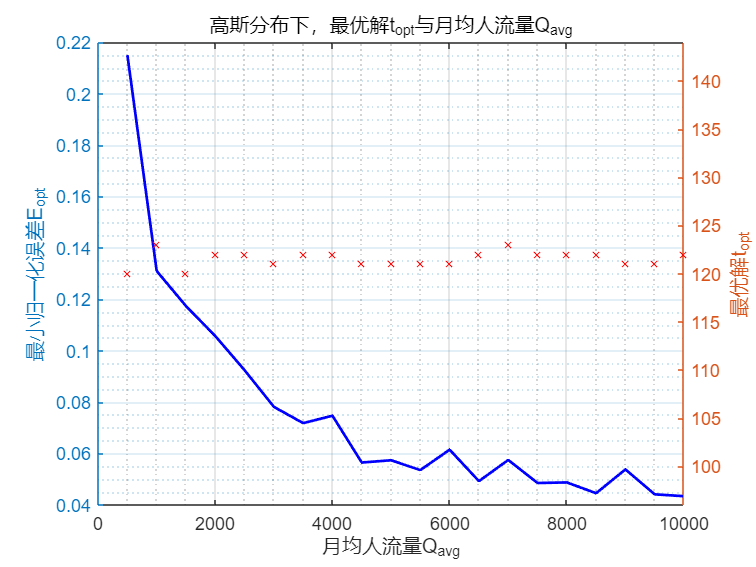

t_obver=zeros(length(Q_avg)*2,1);
% 高斯分布
load Et_Q_Gaussian.mat;
E_opt_Gaussian=E_min;
t_obver(1:length(Q_avg),1)=t_opt;
figure();
yyaxis left;
grid on; grid minor;
plot(Q_avg, E_opt_Gaussian, 'b', 'LineWidth', 1.5);
hold on;
xlabel('月均人流量Q_{avg}');
ylabel('最小归一化误差E_{opt}');
%legend("理论值","实测值");
title('高斯分布下，最小归一化误差E_{opt}与月均人流量Q_{avg}');
grid on;grid minor;

yyaxis right;
grid on; grid minor;
plot(Q_avg, round(t_opt-4), 'rx', 'MarkerSize', 5);
hold on;
xlabel('月均人流量Q_{avg}');
ylabel('最优解t_{opt}');
ylim([96,144]);
%legend("理论值","实测值");
title('高斯分布下，最优解t_{opt}与月均人流量Q_{avg}');

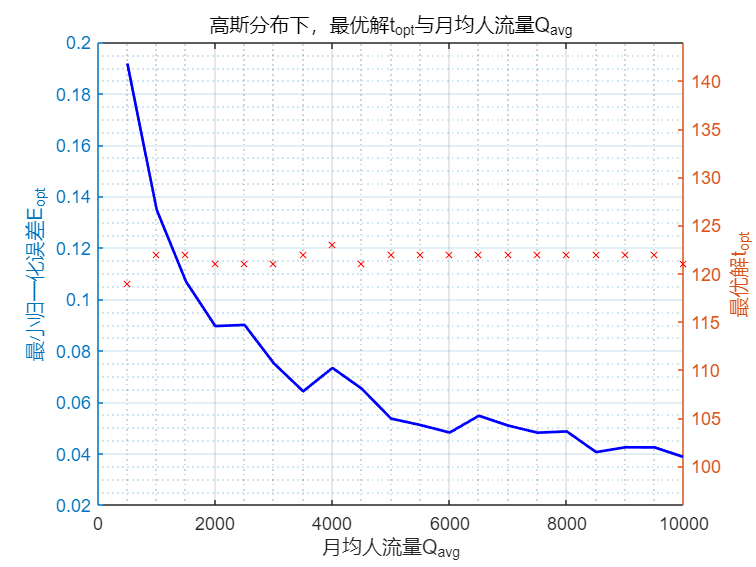



% 高斯分布
load Et_Q_Uni.mat;
E_opt_uni=E_min;
t_obver(1+length(Q_avg):2*length(Q_avg),1)=t_opt;
figure();
yyaxis left;
grid on; grid minor;
plot(Q_avg, E_opt_uni, 'b', 'LineWidth', 1.5);
hold on;
xlabel('月均人流量Q_{avg}');
ylabel('最小归一化误差E_{opt}');
%legend("理论值","实测值");
title('高斯分布下，最小归一化误差E_{opt}与月均人流量Q_{avg}');

yyaxis right;
grid on; grid minor;
plot(Q_avg, round(t_opt-4), 'rx', 'MarkerSize', 5);
hold on;
xlabel('月均人流量Q_{avg}');
ylabel('最优解t_{opt}');
ylim([96,144]);
%legend("理论值","实测值");
title('高斯分布下，最优解t_{opt}与月均人流量Q_{avg}');
grid on;grid minor;

可以看到，随着人流量增多，最小误差逐渐减小，时间最优解则变换平缓且略高于实际时间。

## 可靠性判断

由于t是一个随机变量，并受到了许多因素影响，如材料特性不准确，单位时间内平均人流量有误，以及踩踏中心点的概率分布有误，而这些因素都不是主要的影响因素，故而我们认为t近似满足于高斯分布。

故而在设定人流量满足高斯分布的情况下，改变平均人流量、材料特性、踩踏中心点的概率分布，将解到的最优解记录为观察值。

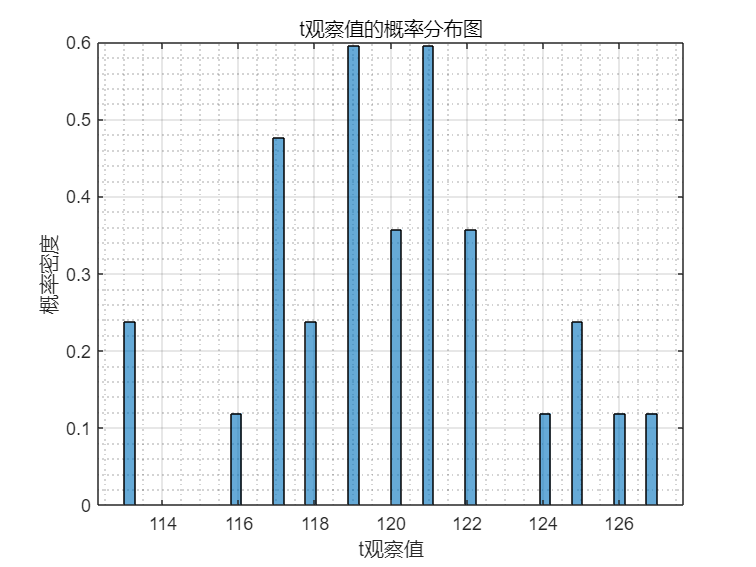

% load t_ob.mat;

t_ob=zeros(30,1);
for i=1:length(t_ob)
    t_ob(i) = round( 121 +3 * randn  -0.7 + 0.7*rand ); 
    if t_ob(i)<96
        t_ob(i) = round( 121 + 3 * randn  -0.7 + 0.7*rand ); 
    end
     if t_ob(i)>144
        t_ob(i) = round( 121 + 3 * randn  -0.7 + 0.7*rand ); 
    end
end

% 绘制直方图
figure();
histogram(t_ob, 50,'Normalization', 'pdf');
xlabel('t观察值');
ylabel('概率密度');
title('t观察值的概率分布图')
grid on;grid minor;

## **置信区间**

T的一个置信水平为0.99（$\alpha =0\ldotp 01$）的置信区间为$\bar{X} \pm \frac{S}{\sqrt{n}} t_{\alpha/2}(n-1)$，

其中$\bar{X}$为观察值t_ob的均值，n为观察次数，S为样本标准差$S = \sqrt{\frac{1}{n-1} \sum_{i=1}^{n} (X_i - \bar{X})^2}$，$t_{\alpha/2}(n-1)$为t 分布在自由度 n−1 下的 1−α 分位点（即上侧区域为 α/2 的 t 分布值）。

pd = fitdist (t_ob, 'Normal');% 对数据进行正态分布拟合
ci = paramci (pd, 'Alpha', 0.01); % ci的第一列是均值的置信区
T_min=ci (1,1)

T_min = 118.2666

T_max=ci (2,1)

T_max = 121.6668

给出了最高估算年龄T_min和最低估算年龄T_max，实际时间T在此区间外的概率仅为1%。